# Introduction to the Maglev simulator

This code-base implements a model of a maglev system on the form illustrated in these figures:

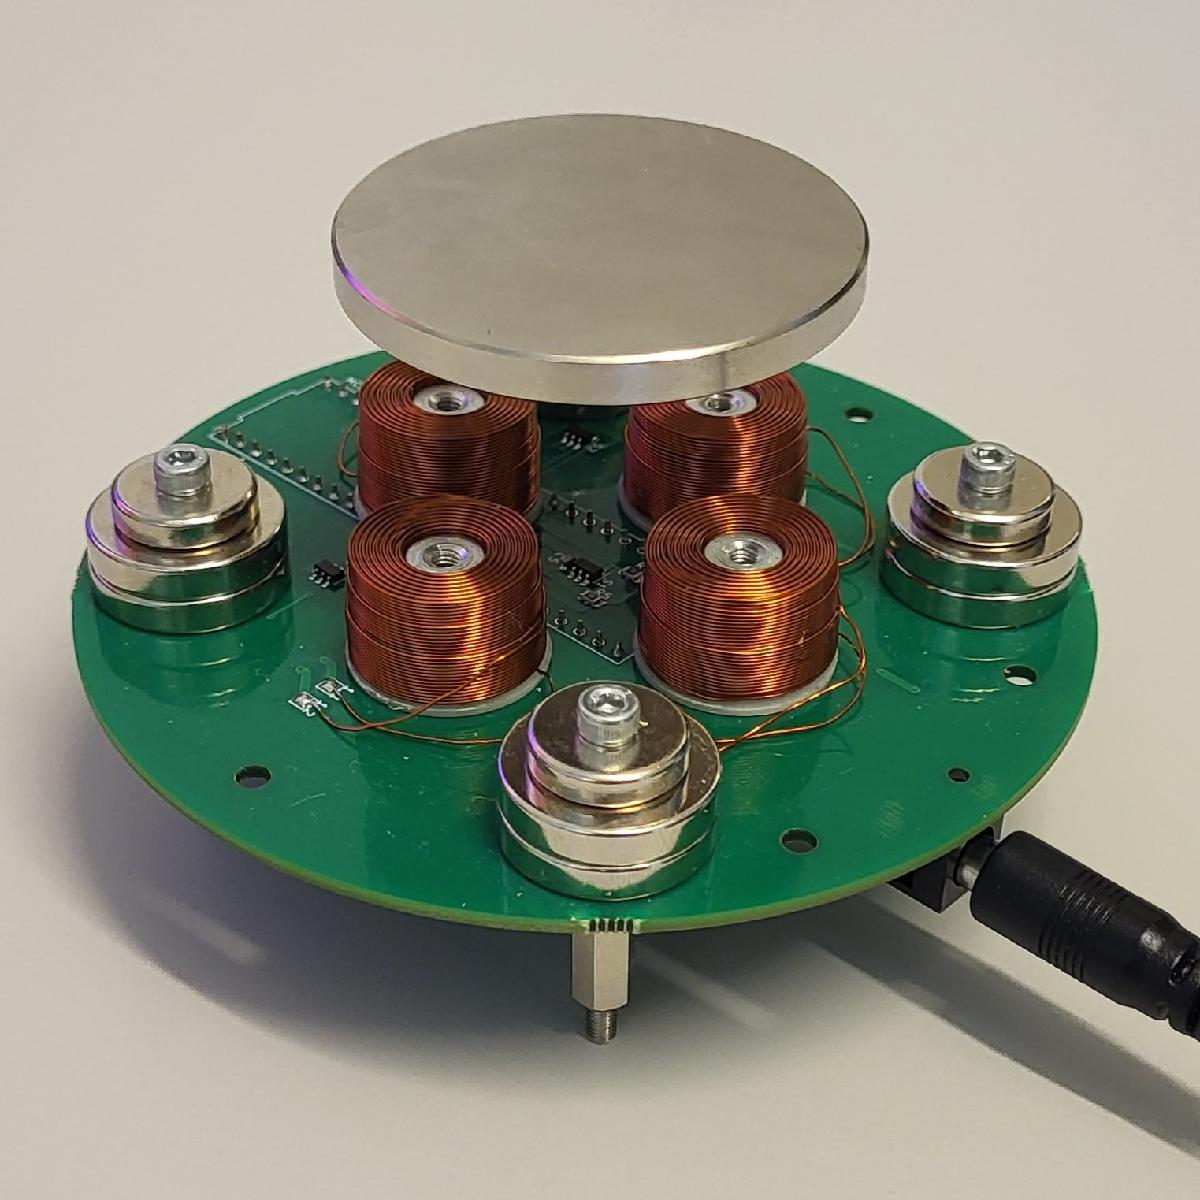   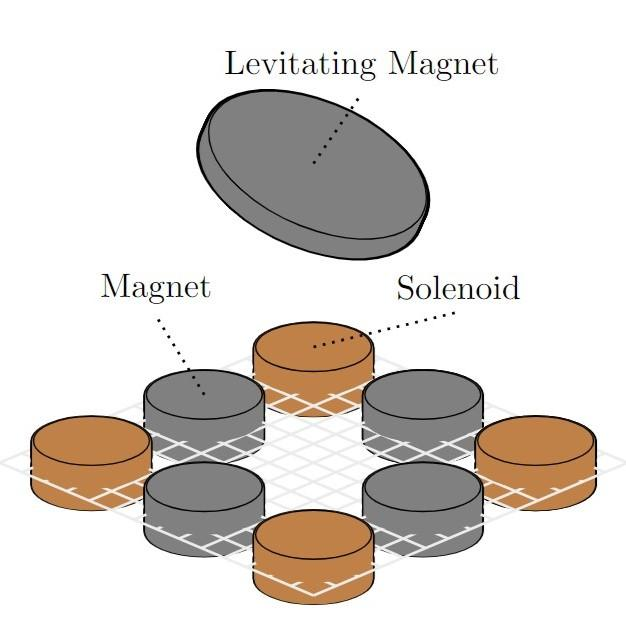         

The simulator is an implementation of the model described in [this paper](https://www.sciencedirect.com/science/article/pii/S240589632300705X). The simulator consists of three models:

- Fast (low fidelity, high speed - model 2 from the paper)

- Accurate (medium fidelity, medium speed - model 1 from the paper)

- filament (high-fidelity, low speed - filament from the paper)   

All three models are on the form

$\begin{array}{l}
\dot{x} =f\left(x,u,\theta \right)\\
y=h\left(x,u,\theta \right)
\end{array}$  (1)

where $x$ is the position & orientation, and their time derivatives, of the levitating magnet, and $u$ is current running through the solenoids. The parameters $\theta$ define the geometric and electromagnetic properties of the system.

In the code base, (1) is represented by the following two functions:

The parameters are stored in structs called *params,* which are defined in separate .m files. The following code examples demonstrate how to load parameter sets, how to illustrate the system and models, how to run simulations, and so on.

Documentation for each function can be found by running the following command in the command window:

## Loading system parameters

### System parameters "params" for Maggy V2

The parameters of a system are loaded by simply calling the .m function containing them.

parameters_maggy_V2;

New parameter sets can be defined by adding new parameter files in the *system_parameters *folder.

## System illustrations

The simulator contains two approaches to illustrate the system and model; (1) the *artistic *illustration, which illustrates the overall system, and (2) the *realistic* illustrations, which illustrate the actual elements used in solving each model representation.

#### The 'artistic' view

All components are illustrades as closed cylinders, with dimensions matching those of the real system.

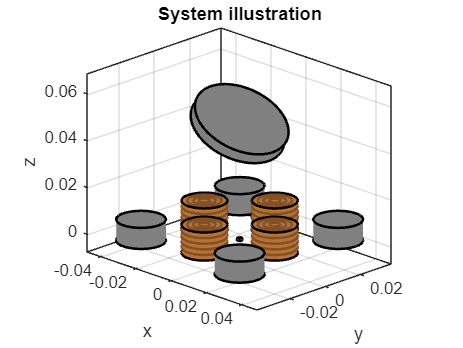

figure(1); clf; grid on; hold on; box on; axis equal; view([45,20]);
title('System illustration')

plotBaseArtistic(params);
plotMagnetArtistic(0,0,0.05,0,0.5,0.5,params);

xlabel('x')
ylabel('y')
zlabel('z')

#### The 'fast' model

Solenoids and permanent magnets are represented using thin wire loops, centered at the middle of each solenoid/magnet in the axial direction. Notice that the solenoids have a smaller radius than above, which is necessary for a more accurate model representation (compared to the filament model). The levitating magnet consists of $n$ linear segments in a loop.

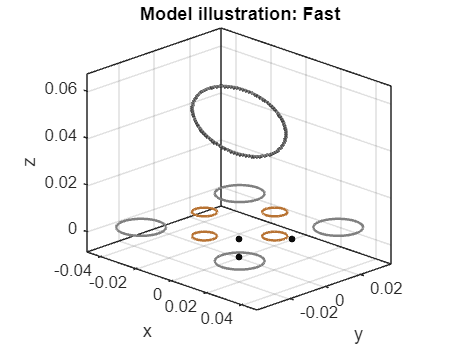

figure(2); clf; grid on; hold on; box on; axis equal; view([45,20]);
title('Model illustration: Fast')

plotBaseRealistic(params,'fast');
plotMagnetRealistic(0,0,0.05,0,0.5,0.5,params,'fast');

xlabel('x')
ylabel('y')
zlabel('z')

#### The 'accurate' model

Solenoids and permanent magnets are represented using thin-walled cylinders, i.e., ideal solenoids. This is an accurate representation of the permanent magnets, but the solenoids need radius correction similar to the 'fast' model. The levitating magnet is now represented as a cylindrical surface, and the force is computed as an integral over this surface.

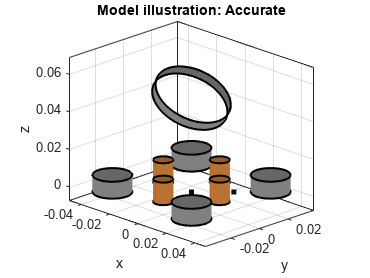

figure(3); clf; grid on; hold on; box on; axis equal; view([45,20]);
title('Model illustration: Accurate')

plotBaseRealistic(params,'accurate');
plotMagnetRealistic(0,0,0.05,0,0.5,0.5,params,'accurate');

xlabel('x')
ylabel('y')
zlabel('z')

#### The 'filament' model

Permanent magnets and the levitating magnet are represented the same way as in the 'accurate' model, however, the solenoids now consist of a dense number of thin wire loops, which closely mimic the true solenoids.

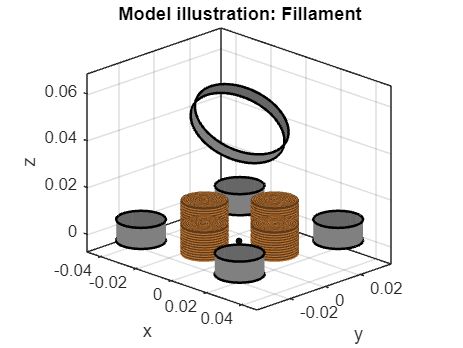

figure(4); clf; grid on; hold on; box on; axis equal; view([45,20]);
title('Model illustration: filament')

plotBaseRealistic(params,'filament');
plotMagnetRealistic(0,0,0.05,0,0.5,0.5,params,'filament');    

xlabel('x')
ylabel('y')
zlabel('z')

## Correcting 'fast' and 'accurate'

As mentioned in the previous section, the 'fast' and 'accurate' models require correction of the solenoid radius in order to more closely mimic the effect of having windings spread out in the radial direction in real solenoids. The correction is performed by optimizing a correction factor $c$ so that the corrected radius $r_{\mathrm{corrected}} =c\cdot r$ minimize the norm of the difference between the magnetic field produced by these models, and the 'filament' model.

### **Computing correction factors**

correctionFactorFast = computeSolenoidRadiusCorrectionFactor(params,'fast');
correctionFactorAccurate = computeSolenoidRadiusCorrectionFactor(params,'accurate');

fprintf('Fast correction factor %.2f\n', correctionFactorFast)

Fast correction factor 0.56


fprintf('Accurate correction factor %.2f\n', correctionFactorAccurate)

Accurate correction factor 0.55


### **Updating parameter sets**

After correcting, we need to update the parameter sets that we are going to use when simulating 'fast' and 'accurate' with the new radius.

paramsFast = params;
paramsFast.solenoids.r = correctionFactorFast*paramsFast.solenoids.r;

paramsAccurate = params;
paramsAccurate.solenoids.r = correctionFactorAccurate*paramsAccurate.solenoids.r;

## Analyzing equilibria

### Computing equilibria

The easiest way to achieve stable levitation is to stabilize towards system equilibria along the z-axis. These can easily be found (in this case, for the 'fast' model) using the following function.

[zEq, zEqInv, dzEq, dzEqInv] = computeSystemEquilibria(paramsFast,'fast');

### The vertical force curve

A convenient tool for analyzing system equilibria is to look at the force on the magnet when it is placed parallel with the xy-axis, and along different points on the z-axis*. *The force will then only act in the z direction, and the equilibria are found where $f_z =0$. This figure also shows the force when flipping the magnet 180 degrees, which for some systems might also yield equilibria, i.e., there are systems where the magnet can feasibly levitate in both orientations!

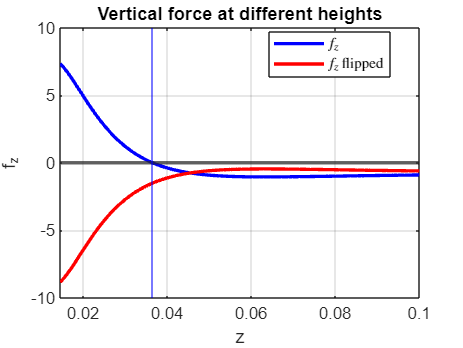

% Defining range
zMin = max([params.solenoids.z+params.solenoids.l/2, params.permanent.z+params.permanent.l/2]) + params.magnet.l/2; % Physical Limitations
zMax = 0.1; % Arbitrarily chosen
z = linspace(zMin,zMax,100);

% Computing vertical force
[fzFast, fzInvFast] = computeVerticalForce(z,paramsFast,'fast');

% Plotting
figure(2); clf; grid on; hold on; box on;
title('Vertical force at different heights')

plot(z,fzFast,'b','linewidth',2,'DisplayName','$f_z$')
plot(z,fzInvFast,'r','linewidth',2,'DisplayName','$f_z$ flipped')
yline(0,'linewidth',2,'HandleVisibility','off')

xlim([zMin, zMax])
xlabel('z')
ylabel('f_z')
legend('location','best','interpreter','latex')

try
    xline(zEq,'b','HandleVisibility','off')
catch
end


try
    xline(zEqInv,'r','HandleVisibility','off')
catch
end

## Illustrating the magnetic field

The magnetic field is very easily illustrated for any of the models. 

### Vector field

Here, we show how to plot intersections of the magnetic field vectors on the xz- and yz-plane, at a specific instance in time when no current is running through the solenoids.

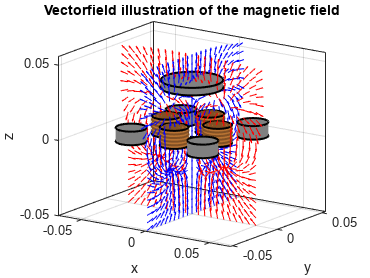

% Assume no input
u = zeros(4,1);

% Define planes in 3D space
[X,Z] = meshgrid(linspace(-0.05,0.05,21));

% Compute magnetic field vectors
[bx,by,bz] = computeFieldBase(X,zeros(size(X)),Z,u,params,'fast');

% Normalize for better visualization
NORM = sqrt(bx.^2 + by.^2 + bz.^2);

bx = bx./NORM;
by = by./NORM;
bz = bz./NORM;

% Plotting using quiver
figure(5); 
clf; grid on; hold on; box on; axis equal; view([35,15]);
title('vector field illustration of the magnetic field')

plotBaseArtistic(params);
plotMagnetArtistic(0,0,zEq(1),0,0,0,params);

quiver3(X,zeros(size(X)),Z,bx,by,bz,'r')
quiver3(zeros(size(X)),X,Z,bx,by,bz,'b')

xlabel('x')
ylabel('y')
zlabel('z')

### Magnitude heatmap

We can also illustrate the field strength (rather than field vectors). Here, we illustrate the field strength in a plane parallell to the xy-plane, just above the magnets/solenoids, when a lot of current is running through the solenoids.

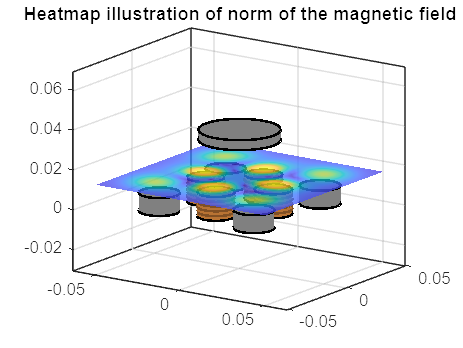

% Assume a lot of input
u = 20*ones(4,1);

% Define planes in 3D
[X,Y] = meshgrid(linspace(-0.05,0.05,31));
[bx,by,bz] = computeFieldBase(X,Y,zMin*ones(size(X)),u,params,'fast');

% Compute the norm (magnitude)
NORM = sqrt(bx.^2 + by.^2 + bz.^2);

% Plotting using surf
figure(6);
clf; grid on; hold on; box on; axis equal; view([35,15]);
title('Heatmap illustration of norm of the magnetic field')

surf(X,Y,1e-3*NORM+zMin,NORM,'faceAlpha',0.75);
shading interp;

plotBaseArtistic(params);
plotMagnetArtistic(0,0,zEq(1),0,0,0,params);

## Linearization

Linearization is an important tool for analyzing stability and designing linear controllers for nonlinear systems. Here, we see how to linearize the maglev system.

% Define the model to be used in linearization
modelName = 'fast';

% Setting up system equations with speficied model and parameters for
% simpler representation
f = @(x,u) maglevSystemDynamics(x,u,paramsFast,modelName);
h = @(x,u) maglevSystemMeasurements(x,u,paramsFast,modelName);

% Define the point to linearize around
xLp = [0,0,zEq(1),zeros(1,9)]'; % Linearizing around the equilibria
uLp = zeros(length(params.solenoids.r),1);

% Linearization
delta = 1e-6; % Step-size used in numerical linearization
[A,B,C,D] = finiteDifferenceLinearization(f,h,xLp,uLp,delta);

fprintf('Size of A: %.f, %.f\n', size(A))

Size of A: 12, 12


fprintf('Size of B: %.f, %.f\n', size(B))

Size of B: 12, 4


fprintf('Size of C: %.f, %.f\n', size(C))

Size of C: 9, 12


fprintf('Size of D: %.f, %.f\n', size(D))

Size of D: 9, 4


## LQR control

Using the linearized model from above, we can define a simple LQR controller in order to stabilize the system at the equilibrium.

### Designing LQR controller

The rotation around the center axis of the levitating magnet is uncontrollable. Thus, the rotation of the linear model is uncontrollable around the z-axis (since the axis of the magnet is parallel with it in the equilibrium). Luckily, we do not need to worry about this axis when controlling the system because it does not affect any of the other states in the linear model, so we may just remove them from the linear model when designing our controller:

% Defining reduced order system
I = [1:5,7:11];
Ared = A(I,I);
Bred = B(I,:);
Cred = C(:,I);
Dred = D(:,:);

% Cost matrices
Q = diag([1e6,1e6,1e2, 1e1,1e1, 1e2,1e2,1e2, 1e2,1e2]);
R = 1e-0*eye(length(params.solenoids.r));

% Computing LQR estimate
Kred = round(lqr(Ared,Bred,Q,R),3); % Rounding can sometimes be dangerous!

% increasing order of our controller for controlling the real system
K = [Kred(:,1:5), zeros(4,1), Kred(:,6:end), zeros(4,1)];


### Simulating the system

We can easily simulate the system using the above LQR controller. Notice that ode15s is used for simulation; the system is stiff and requires a stiff solver.

% Simulation setup
x0 = xLp + [0.001 -0.003 0.04 pi/5 0 0 zeros(1, 6)].';
tSpan = linspace(0,1,100);

% Simulation
tic
[t,x] = ode15s(@(t,x) f(x,-K*(x-xLp)-uLp), tSpan, x0);

fprintf('LQR simulation time: %.2fs\n', toc)

LQR simulation time: 1.49s


### Plotting results

We plot the position of the center of the magnet to see the results of the simulation.

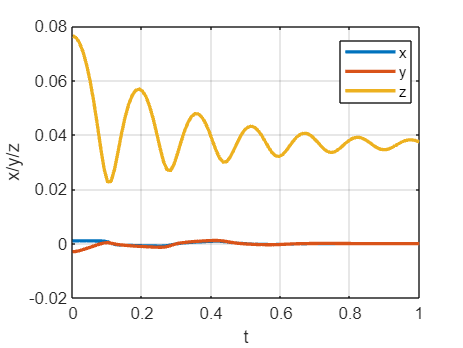

figure(7);
clf; grid on; hold on; box on;

plot(t,x(:,1:3),'linewidth',2)

xlabel('t')
ylabel('x/y/z')
legend({'x','y','z'},'location','best')

## Animation

We may use the plotting code used in the beginning to make an animation of the simulation results. **OBS: ***Deleting and redrawing the magnetic field as done here is not efficient. For faster rendering, it is better to only update the data at each point. The updatePositionOfObject function does this for the levitating magnet. To see the difference in speed, comment out the code for plotting the magnetic field.*

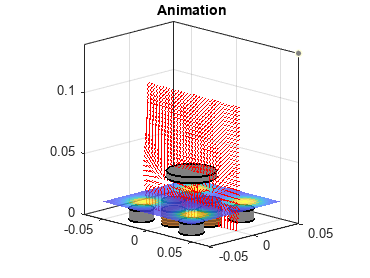

% Defining the plane(s) we want to evaluate the magnetic field
[X,Z] = meshgrid(linspace(-0.05,0.05,31));

% Figure setup
figure(8);
clf; grid on; hold on; box on; axis equal; view([45,15]);
title('Animation')
xlim([-0.07,0.07])
zlim([-0.07,0.07]+0.07)

plotBaseArtistic(params);
H = plotMagnetArtistic(0,0,0.05,0,0,0,params);

% Animation 
for i = 1:length(t)
    % Compute & plot magnetic field
    u = -K*(x(i,:)'-xLp)-uLp;
    [bx,by,bz] = computeFieldTotal(X,zeros(size(X)),Z+0.05,x(i,:)',u,params,'fast');

    NORM = sqrt(bx.^2 + by.^2 + bz.^2);
    
    bx = bx./NORM;
    by = by./NORM;
    bz = bz./NORM;

    try
        delete(hField);
    catch
    end
    hField = quiver3(X,zeros(size(X)),Z+0.05,bx,by,bz,'r');

    % Compute surface field
    [bx,by,bz] = computeFieldTotal(X,Z,zMin*ones(size(X)),x(i,:)',u,params,'fast');

    NORM = sqrt(bx.^2 + by.^2 + bz.^2);
    
    try
        delete(hSurf);
    catch
    end
    hSurf = surf(X,Z,1e-6*NORM+zMin,NORM,'faceAlpha',0.75,'EdgeColor','none');

    % Update magnet position
    updatePositionOfObject(H,x(i,1),x(i,2),x(i,3),x(i,4),x(i,5),x(i,6));
    drawnow;
end